%{
ES115 Engineering Computer Applications 
Module 1 Project: Profit vs Production

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 25, 2026

Purpose:
The purpose of this project is to analyze a startup's financial health by modeling its
revenue, costs, and profit. Using MATLAB to compare linear income against quadratic 
expenses allows us to find the most profitable production level and identify "break-even" 
points where the business stops losing money. This demonstrates how mathematical modeling
helps companies optimize their production to ensure long-term success.

Inputs:
- Production Range (x): 0 to 80 units
- Step Size: 1 unit
- Financial Constants: Unit price (p), fixed costs (c), and variable cost coefficients (a, b)

Outputs:
- Financial Vectors: Calculated values for Revenue (R), Cost (C), and Profit (P)
- Optimal Production Level: The unit count (x) that generates the maximum profit
- Break-even Points: The production levels where Profit (P) is approximately zero
- Visualization: A comprehensive plot showing the relationship between Revenue, Cost, and Profit

Engineering Workflows:
- Economic Modeling: Representing business variables as linear and quadratic functions
- Numerical Optimization: Determining the peak of a function within a discrete range of values
- Root-Finding/Intersection Analysis: Identifying the points where income offsets expenses

MATLAB Tools:
- Vector Operations: Evaluating entire equations across the range of (x) without loops
- max(): Finding the highest value in the Profit vector and its corresponding index
- find() and diff(): Using sign changes in the data to detect where the profit crosses zero
- plot() and legend(): Creating and labeling clear visual data comparisons
%}


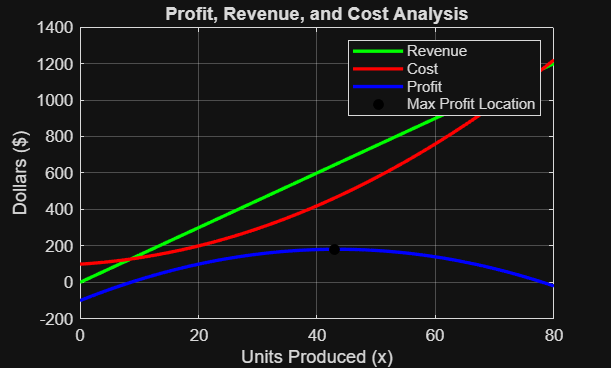

x = 0:1:80;

p = 15;        
a = 0.15;      
b = 2;         
c = 100;       

R = p * x;
C = a * x.^2 + b * x + c;
P = R - C;

[max_P, idx] = max(P);
x_opt = x(idx);

break_even_indices = find(diff(sign(P)) ~= 0);
break_even_x = x(break_even_indices);

figure;
plot(x, R, 'g', 'LineWidth', 2); hold on;
plot(x, C, 'r', 'LineWidth', 2);
plot(x, P, 'b', 'LineWidth', 2);
plot(x_opt, max_P, 'ko', 'MarkerFaceColor', 'k');
grid on;
xlabel('Units Produced (x)');
ylabel('Dollars ($)');
title('Profit, Revenue, and Cost Analysis');
legend('Revenue', 'Cost', 'Profit', 'Max Profit Location');


fprintf('Maximum Profit of $%.2f occurs at %d units.\n', max_P, x_opt);

Maximum Profit of $181.65 occurs at 43 units.


if ~isempty(break_even_x)
    fprintf('Approximate Break-even Points occur near: %s units.\n', num2str(break_even_x));
end

Approximate Break-even Points occur near: 8  78 units.
